# MTRN4230 T2 2020

   %{
    THINGS TO DO
    1.  make a home configuration
    1.5 get simulation down pat + are we using grippers, vacuum what is the
    size of conveyor/positions everything necessary for #2-path planning
    2.  make path/trajectory planning algorithm
    3.  kinematics equations using home config and path plan, turn in into
    an algorithm?
    4.  find a way to return outputs of algorithms and make it apply to
    robot (i/o maybe?) need to discuss
   %}

## SETUP/CONNECT TO GAZEBO/ROS

clear all;
clear variables;
close all;
clc;
ipaddress = '192.168.0.18';
robotType = 'Gazebo';
rosshutdown;

Shutting down global node /matlab_global_node_32411 with NodeURI http://192.168.0.10:54902/


rosinit(ipaddress);

Initializing global node /matlab_global_node_79395 with NodeURI http://192.168.0.10:55158/


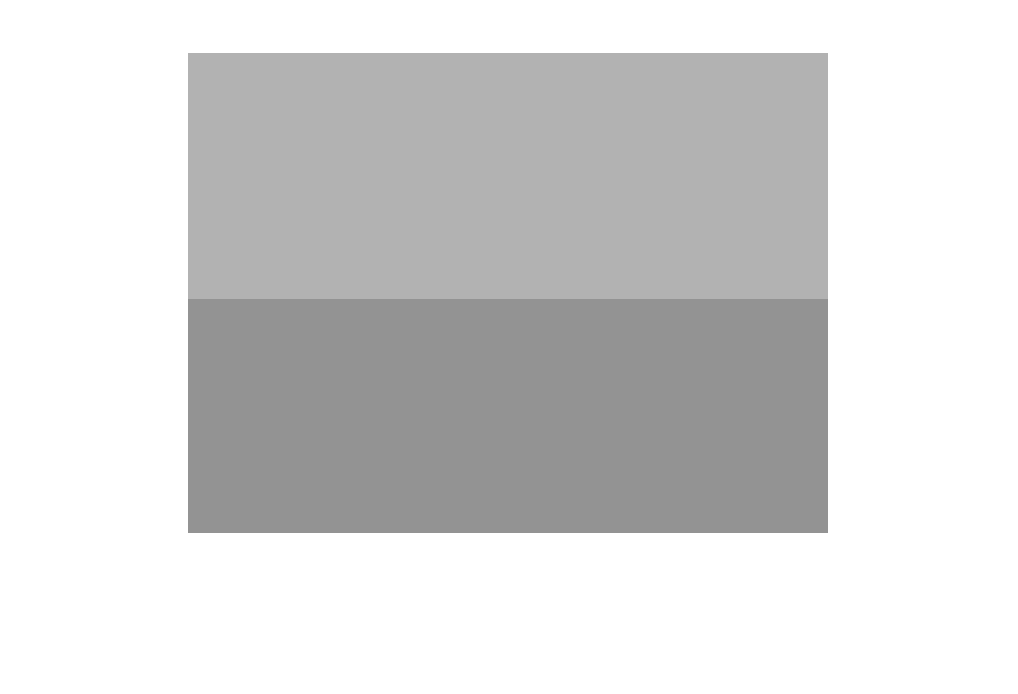

blockposes = rossubscriber('/gazebo/link_states');
pause(2);
posdata = receive(blockposes,10);
imSub = rossubscriber('/camera/color/image_raw');
pcSub = rossubscriber('/camera/depth/points');
testIm  = readImage(imSub.LatestMessage);
imshow(testIm);

rostopic list;

/arm_controller/command                                       
/arm_controller/follow_joint_trajectory/cancel                
/arm_controller/follow_joint_trajectory/feedback              
/arm_controller/follow_joint_trajectory/goal                  
/arm_controller/follow_joint_trajectory/result                
/arm_controller/follow_joint_trajectory/status                
/arm_controller/state                                         
/calibrated                                                   
/camera/color/camera_info                                     
/camera/color/image_raw                                       
/camera/color/image_raw/compressed                            
/camera/color/image_raw/compressed/parameter_descriptions     
/camera/color/image_raw/compressed/parameter_updates          
/camera/color/image_raw/compressedDepth                       
/camera/color/image_raw/compressedDepth/parameter_descriptions
/camera/color/image_raw/compressedDepth/parameter_updat

## load the robot

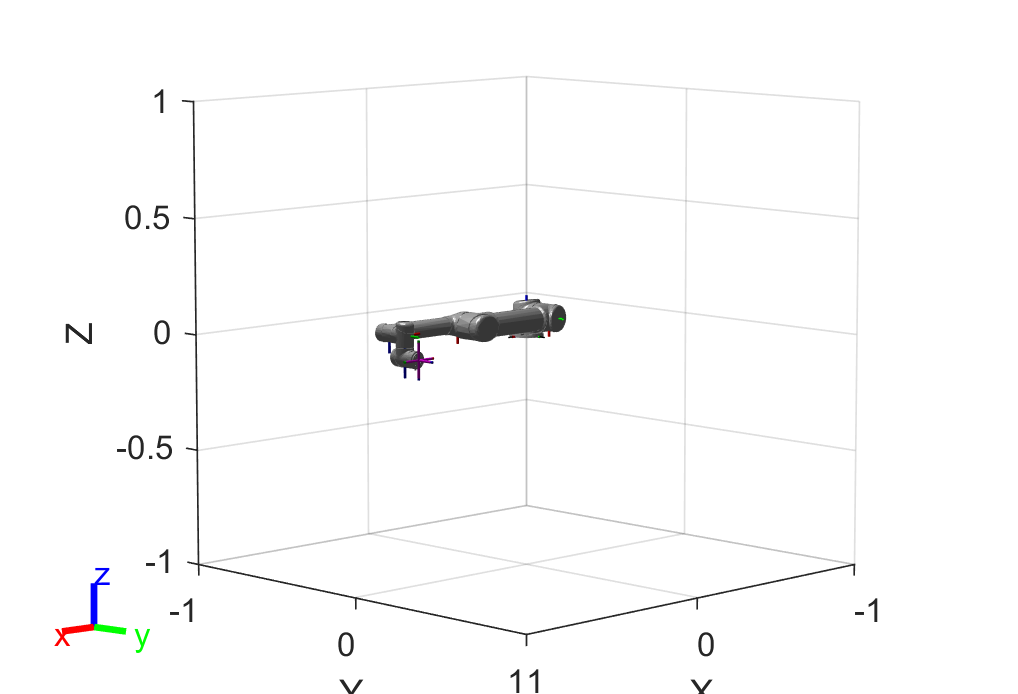

%In MATLAB, not Gazebo/ROS
robot = loadrobot("universalUR5");
%robot = rigidBodyTree; %load the UR5 into a rigidBodyTree
%for now use a random frame for the calcs since we don't have path planning
%yet- need a simulation for that
figure(1);
randPos = randomConfiguration(robot);
show(robot);

show(robot,randPos);
showdetails(robot);

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

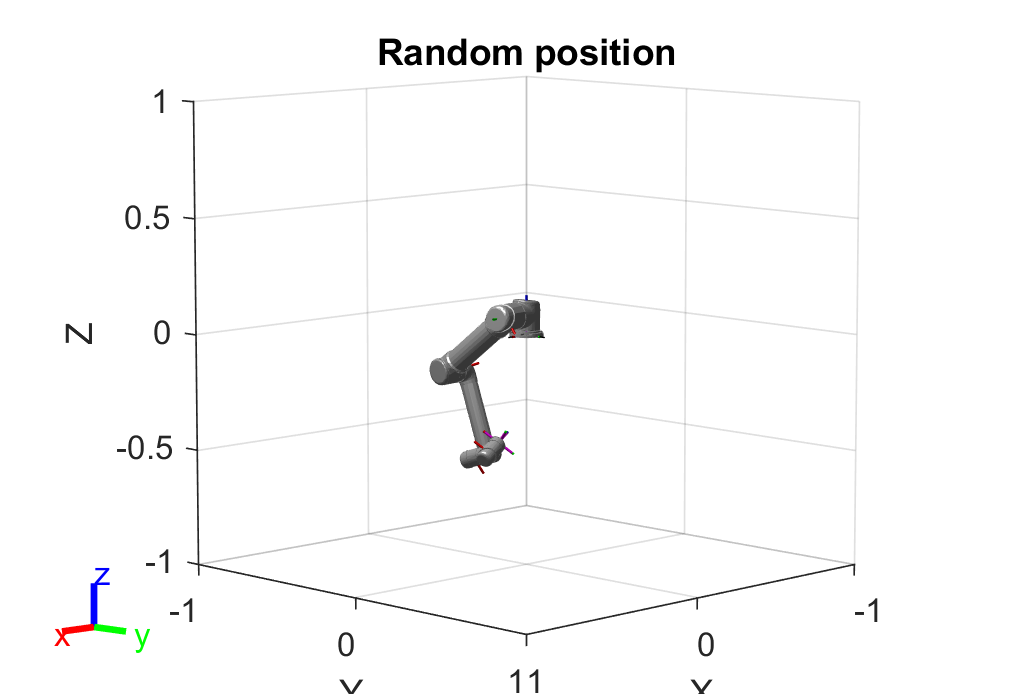

title('Random position');

## Joint States

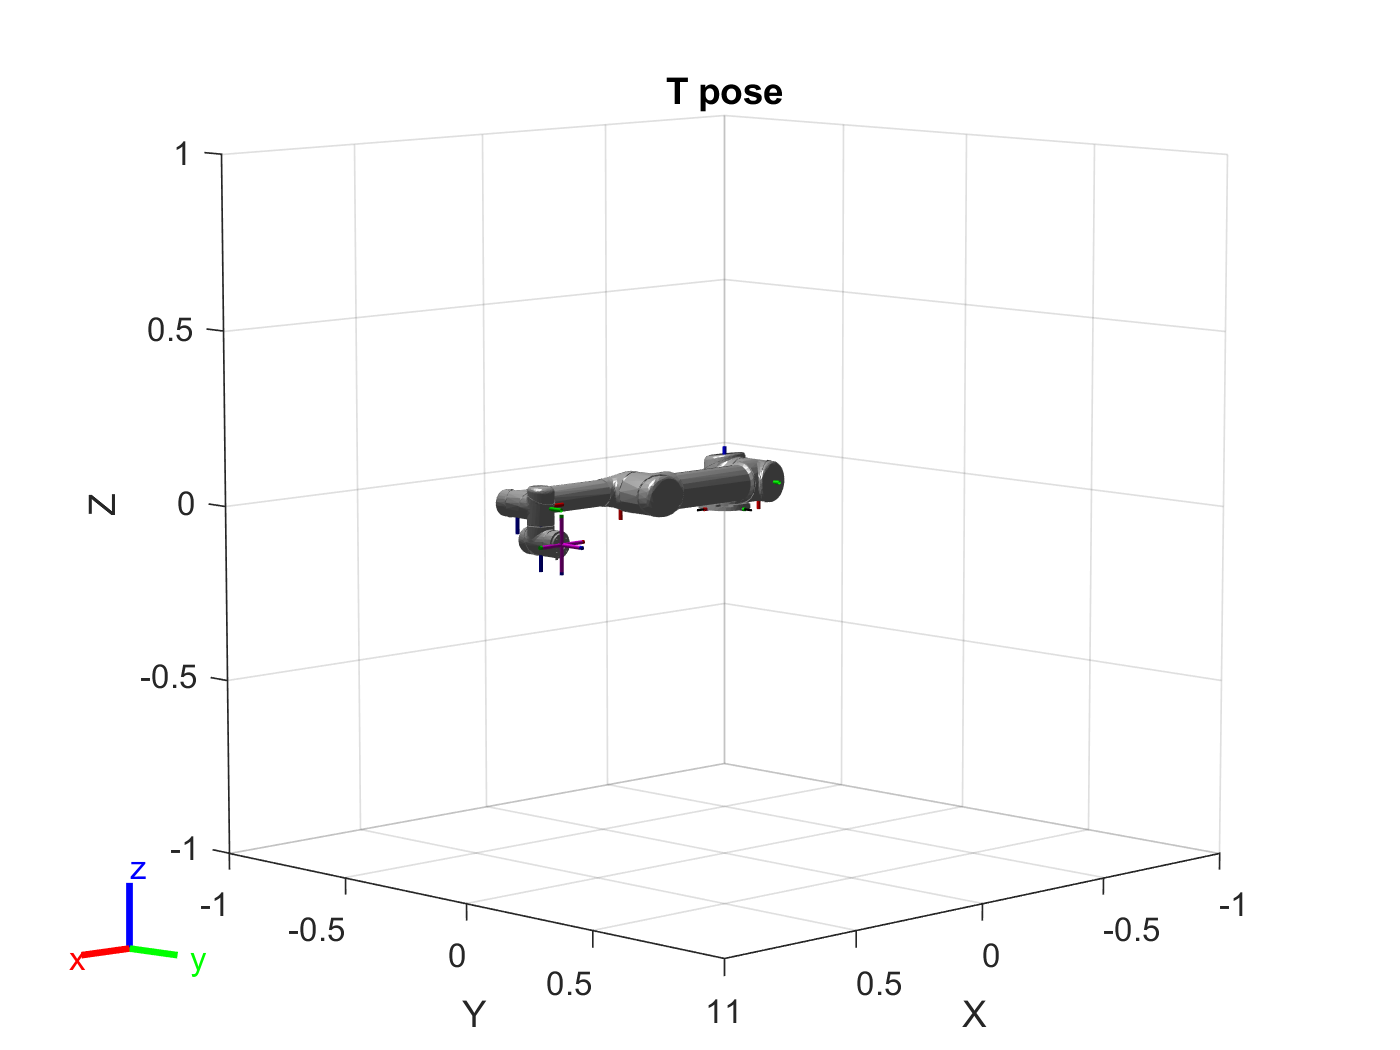

%Currently only records robot state at the instant the commands are called
%- need to put in a loop with the rest of the commands
jointSub = rossubscriber('joint_states'); %Needs to connect to ROS/Gazebo?
jntState = receive(jointSub);
jntPos = exampleHelperJointMsgToStruct(robot,jntState);
figure(2);
show(robot);
title('T pose'); %Shows robot in default state a robot T pose if you will

%show(robot,jntState.Position); %Doesn't work since it expects a struct not
%a jointstate
show(robot,jntPos);
showdetails(robot);

--------------------
Robot: (10 bodies)

 Idx             Body Name                            Joint Name                            Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                            ----------                            ----------             ----------------   ----------------
   1             base_link                           world_joint                                 fixed                     world(0)   base(2)  shoulder_link(3)  
   2                  base            base_link-base_fixed_joint                                 fixed                 base_link(1)   
   3         shoulder_link                    shoulder_pan_joint                              revolute                 base_link(1)   upper_arm_link(4)  
   4        upper_arm_link                   shoulder_lift_joint                              revolute             shoulder_link(3)   forearm_link(5)  
   5          forearm_link                           e

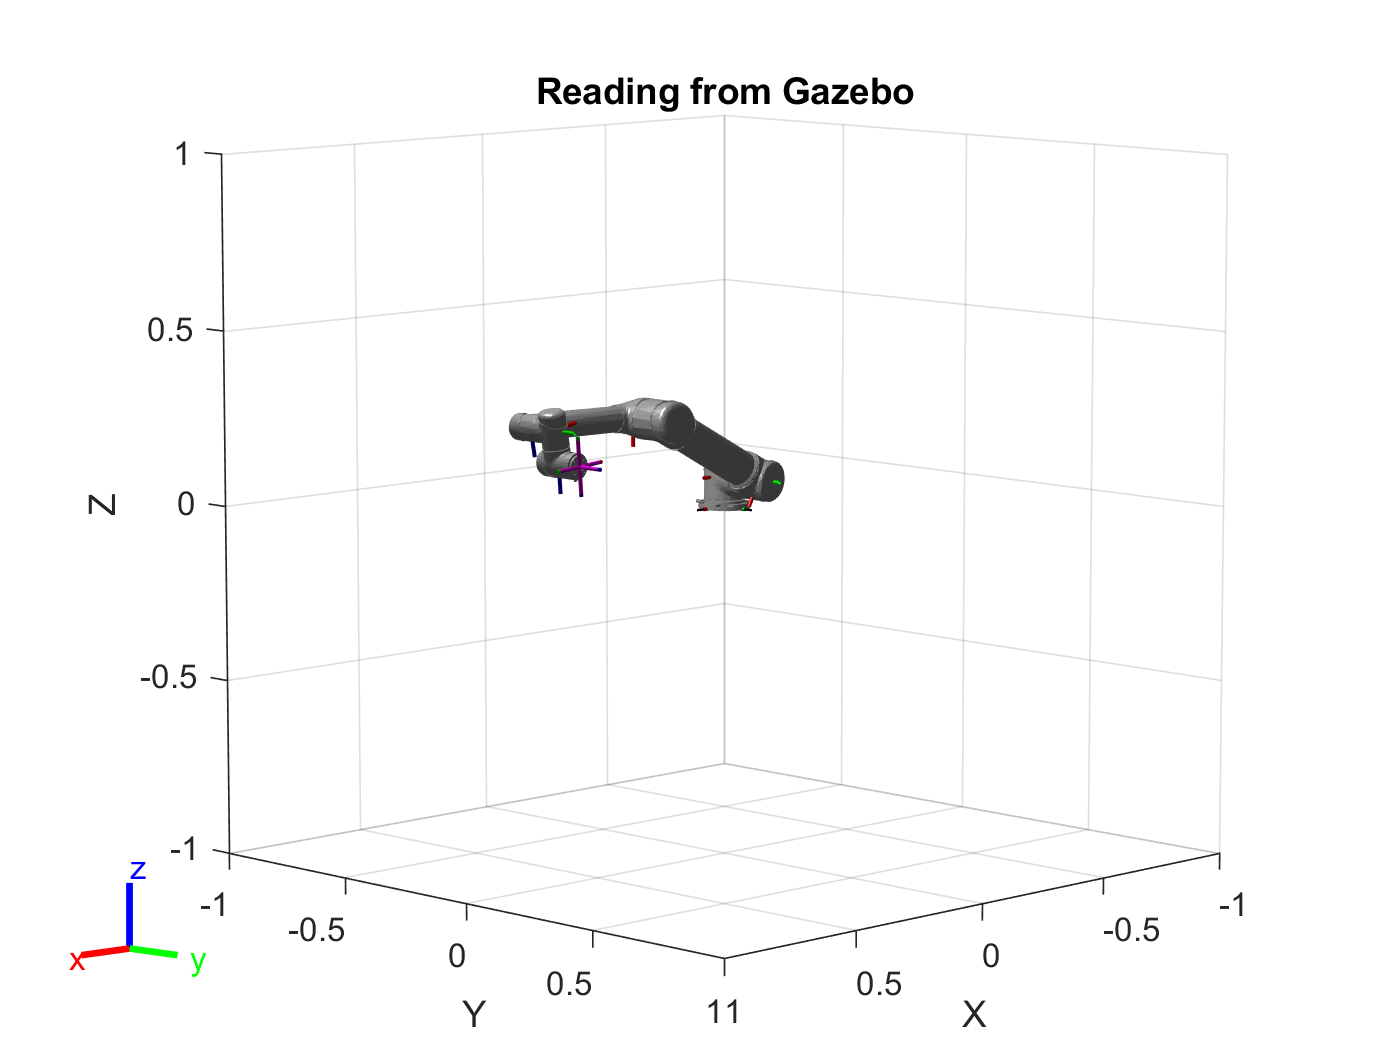

title('Reading from Gazebo')

%jntPos = exampleHelperJointMsgToStruct(ur5,jntState);
%Appears to copy the current motion  of the robot and displays in diagram

## kinematic equations

%getTransform does all the kinematics calcs for you but you need two
%coordinate frames. Right now it is the default(flat) robot frame and a
%randomly generated one. Need to replace the default frame with a
%homeConfiguration and the other frames will be decided based on path
%transform = getTransform(robot,randPos,'upper_arm_link','forearm_link');

%forward kinematics
transform = getTransform(robot,jntPos,'tool0','base')

transform =     0.9969   -0.0784   -0.0001   -0.7491
   -0.0001    0.0000   -1.0000   -0.1914
    0.0784    0.9969    0.0000    0.2020
         0         0         0    1.0000



%inverse kinematics
ik = inverseKinematics('RigidBodyTree',robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = jntPos;
[configSol,solInfo] = ik('tool0',transform,weights,initialguess)

configSol = 1×6 struct array with fields:
    JointName
    JointPosition


solInfo = struct with fields:
           Iterations: 35
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2808e-10
             ExitFlag: 1
               Status: 'success'


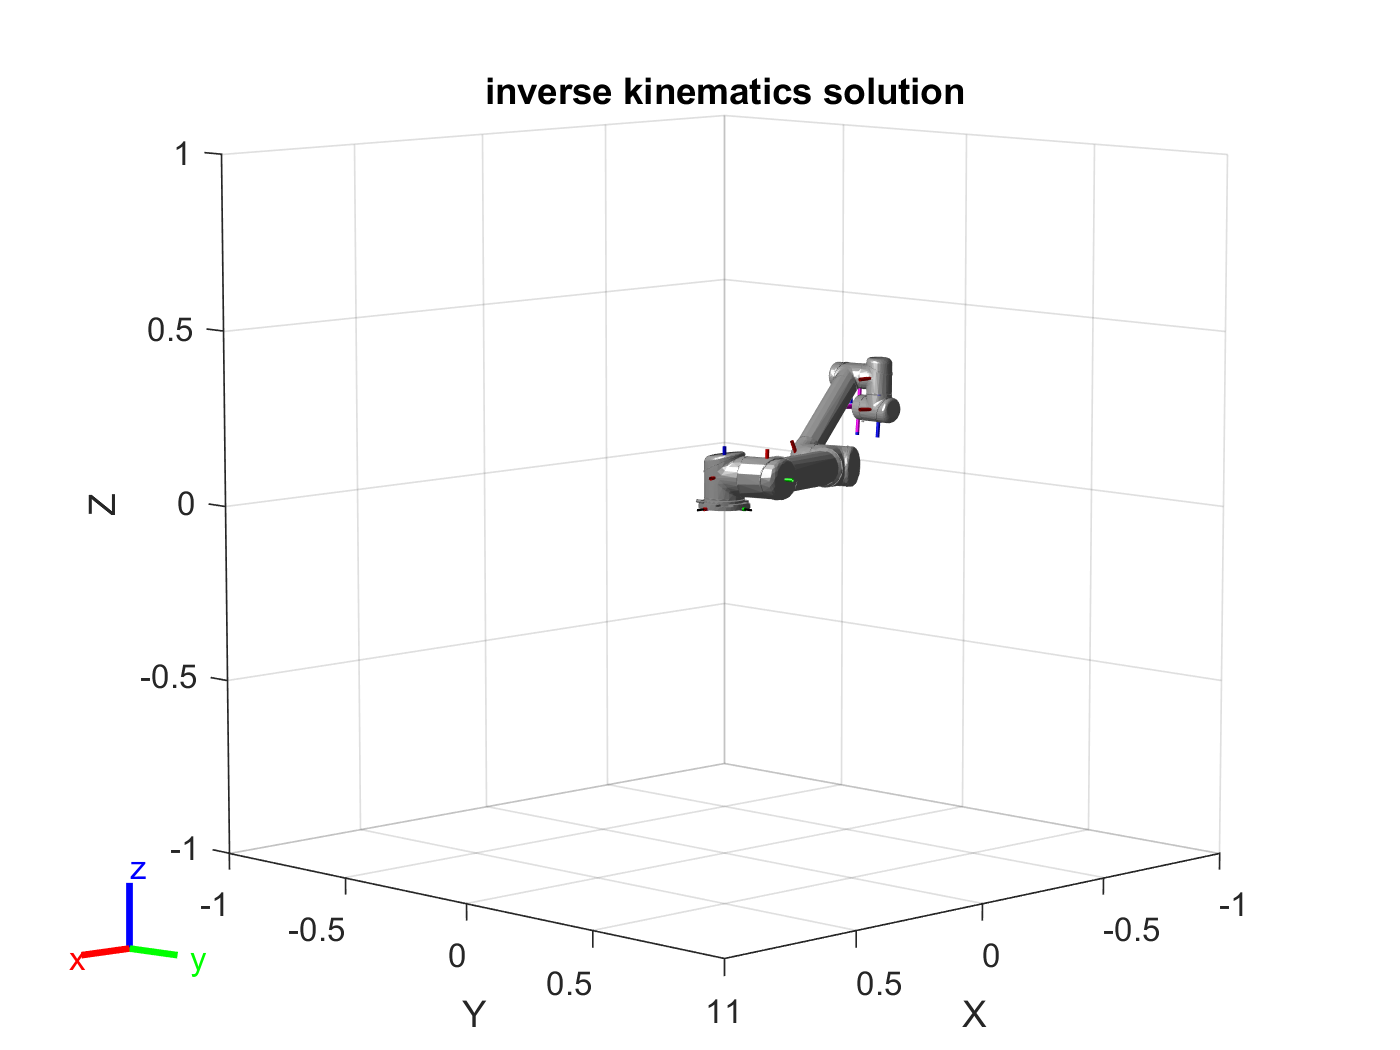

show(robot,configSol);
title('inverse kinematics solution')

## Path Planning

%Set up action client to send commands to robot
[rArm,rGoalMsg] = rosactionclient('/arm_controller/follow_joint_trajectory');
disp(rGoalMsg);

  ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
    GoalTimeTolerance: [1×1 Duration]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]

  Use showdetails to show the contents of the message



%waitForServer(rArm);

%Set the joint names to match the UR5 robot joint name
%rGoalMsg.Trajectory.JointNames = {'shoulder_pan_joint','shoulder_lift_joint','elbow_joint','wrist_1_joint','wrist_2_joint','wrist_3_joint'};

%Define end effector i.e. where coordinates 
endEffector = 'r_gripper_tool_frame';

currentRobotJConfig = homeConfiguration(robot);
jointInit = currentRobotJConfig; %Produces a struct, same as 'jntPos'

%DEFINING MOTIONS - waypoints
%Start and end positions - Get from the robot state?
posStart = trvec2tform([-0.7, -0.5, 0.75]);
posEnd = trvec2tform([0.25, 0.5, 0.25]);
timeStep = 0.1; %seconds
toolSpeed = 0.05; %m/s

%Generate and control task space trajectories - End effector position
taskInit = getTransform(robot,jointInit,'ee_link');
taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]);

distance = norm(tform2trvec(posStart)-tform2trvec(posEnd)); %Calculate end effector travel distance

initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];
%Interpolate between taskInit and taskFinal to compute intermediate task-space waypoints.

[taskWaypoints,taskVelocities] = transformtraj(posStart,posEnd,timeInterval,trajTimes); 

%Create a joint space motion model for PD control on the joints
tsMotionModel = taskSpaceMotionModel('RigidBodyTree',robot,'endEffector','ee_link');
tsMotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;

%Define the initial states (joint positions and velocities).
%Don't confuse with end effector pose!
q0 = jntPos; %currentRobotJConfig; 
qd0 = zeros(size(q0));

%Convert doubles to structs
taskInit = num2cell(taskInit);
taskFinal = num2cell(taskFinal);
taskInit = cell2struct(taskInit,robotType,4);
taskFinal = cell2struct(taskFinal,robotType,4);
timeInterval = num2cell(timeInterval);
timeInterval = cell2struct(timeInterval,endEffector,2);
qd0 = num2cell(qd0);
qd0 = cell2struct(qd0,robotType,6);
%Use ode15 to make a polynomial of the waypoints FIX THISFIS THIS 
%[tTask,stateTask] = ode15s(@(t,state) exampleHelperTimeBasedTaskInputs(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0; qd0]);

%Generate and control joint space trajectories - Joint and link positions
%Taking inverse kinematics calculated earlier...
ctrlpoints = [jointInit',solInfo'];
jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);

Error using cubicpolytraj
Expected wayPoints to be one of these types:

double, single, uint8, uint16, uint32, uint64, int8, int16, int32, int64

Instead its type was struct.

Error in cubicpolytraj (line 62)
    validateattributes(wayPoints, {'numeric'}, {'2d','nonempty','real','finite'}, 'cubicpolytraj','wayPoints');

jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);

## Send commands to ROS/Gazebo to move arm